# Repeat reunion: Agonistic across individuals and Days

## I. Figure of individual behaviors across 5 sessions

%female first

cumsumbehavID = Rdb_CumSum(rdb_rr, betypes, 0);

cumdegutable = CumSumTable(dtt(:,1), rdb_rr, cumsumbehavID); %female degu table but with cumsums (note it's 4D)


%here we are creating tables that show which interaction a degu was
%performing at a given point of each session
cdsum_cag = nan(size(cumdegutable,1), 5*size(cumdegutable,3)-5);
cdsum_str = nan(size(cumdegutable,1), 5*size(cumdegutable,3)-5);

for i = 1:size(cumdegutable,1)
    for j = 1:5 
        dcum_cag = diff(squeeze(cumdegutable(i,5+j,:,:))); %cumsums are cumulative, so have to take the derivative 
        dcum_str = diff(squeeze(cumdegutable(i,10+j,:,:)));
        
         a = repmat(1:5, size(dcum_cag,1),1); %doesn't matter "how much" they were performing that interaction during the time bin, only matters if they were performing it at all
         dcumT = dcum_cag > 0;
         dcumC_cag = dcumT .* a;     
         
         a = repmat(1:5, size(dcum_str,1),1);
         dcumT = dcum_str > 0;
         dcumC_str = dcumT .* a; 
        
         dcumC_cag(dcumC_cag == 0) = nan;
         dcumC_str(dcumC_str == 0) = nan;
        
         cdinds = ((j-1)*600)+(1:600);
         
         cdsum_cag(i,cdinds) = nanmin(dcumC_cag, [], 2); %If there is more than one interaction during a time bin, we prioritize by the following: agonistic > grooming > rear-sniffing > face-face > body sniffing
        cdsum_str(i,cdinds) = nanmin(dcumC_str, [], 2);

    end
end
    cdsum_cag(isnan(cdsum_cag)) = 0;
    cdsum_str(isnan(cdsum_str)) = 0;


        
 %   dcum = dcum+[zeros(1,scb) ; dcum(1:end-1,:)]+[dcum(2:end,:) ; zeros(1,scb)]; % we dilate the behavior by 1 bin (2 s) in both directions. This will ensure overlap in behaviors

% Cd_cell = cell(2,1);
% for j = 1:2
%     if j == 1
%         p_airs = fem_pairs;
%     elseif j == 2
%         p_airs = mal_pairs;
%     end
%     for i = 1:length(p_airs)
%         for k = 1:5
%            cd_inds = ((k-1) * 600)+(1:600);
%            curind = find(rdb_rr.exposurenum' == k & rdb_rr.paircode == p_airs(i)); 
%            if ~isempty(curind)
%                 Cd_cell{j}(i,cd_inds) = Cdsum(curind(1), :);   
%            end
%         end
%     end
%     
% end

Figures of variability across sessions

peakag = nan(size(cdsum_cag,1), 2);
for i = 1:length(peakag)
    for j = 1:2
        if j == 1
          ag = cdsum_cag(i,:) == 1;
          alint = cdsum_cag(i,:) > 0;
        elseif j == 2
          ag = cdsum_str(i,:) == 1;
          alint = cdsum_str(i,:) > 0;
        end
      cdsmooth = fastsmooth(ag, 10, 2);
      cdsmoothall = fastsmooth(alint, 10, 2);
      [~, peakag(i,j)] = max(cdsmooth);
      [~, peakall(i,j)] = max(cdsmoothall);
        
    end
end

%repeat for male

%cumsumbehavIDM = Rdb_CumSum(rdb_rr, betypes, 0);
cumdegutableM = CumSumTable(dttM(:,1), rdb_rr, cumsumbehavID); %female degu table but with cumsums (note it's 4D)


%here we are creating tables that show which interaction a degu was
%performing at a given point of each session
cdsum_cagM = nan(size(cumdegutableM,1), 5*size(cumdegutableM,3)-5);
cdsum_strM = nan(size(cumdegutableM,1), 5*size(cumdegutableM,3)-5);

for i = 1:size(cumdegutableM,1)
    for j = 1:5 
        dcum_cagM = diff(squeeze(cumdegutableM(i,5+j,:,:))); %cumsums are cumulative, so have to take the derivative 
        dcum_strM = diff(squeeze(cumdegutableM(i,10+j,:,:)));
        
         a = repmat(1:5, size(dcum_cagM,1),1); %doesn't matter "how much" they were performing that interaction during the time bin, only matters if they were performing it at all
         dcumTM = dcum_cagM > 0;
         dcumC_cagM = dcumTM .* a;     
         
         a = repmat(1:5, size(dcum_strM,1),1);
         dcumTM = dcum_strM > 0;
         dcumC_strM = dcumTM .* a; 
         
         
         dcumC_cagM(dcumC_cagM == 0) = nan;
         dcumC_strM(dcumC_strM == 0) = nan;
         
         cdinds = ((j-1)*600)+(1:600);
        
         cdsum_cagM(i,cdinds) = nanmin(dcumC_cagM, [], 2); %If there is more than one interaction during a time bin, we prioritize by the following: agonistic > grooming > rear-sniffing > face-face > body sniffing
        cdsum_strM(i,cdinds) = nanmin(dcumC_strM, [], 2);

    end
end

cdsum_cagM(isnan(cdsum_cagM)) = 0;
cdsum_strM(isnan(cdsum_strM)) = 0;
        
 %   dcum = dcum+[zeros(1,scb) ; dcum(1:end-1,:)]+[dcum(2:end,:) ; zeros(1,scb)]; % we dilate the behavior by 1 bin (2 s) in both directions. This will ensure overlap in behaviors

% Cd_cell = cell(2,1);
% for j = 1:2
%     if j == 1
%         p_airs = fem_pairs;
%     elseif j == 2
%         p_airs = mal_pairs;
%     end
%     for i = 1:length(p_airs)
%         for k = 1:5
%            cd_inds = ((k-1) * 600)+(1:600);
%            curind = find(rdb_rr.exposurenum' == k & rdb_rr.paircode == p_airs(i)); 
%            if ~isempty(curind)
%                 Cd_cell{j}(i,cd_inds) = Cdsum(curind(1), :);   
%            end
%         end
%     end
%     
% end

Figures of variability across sessions

peakagM = nan(size(cdsum_cagM,1), 2);
for i = 1:length(peakagM)
    for j = 1:2
        if j == 1
          ag = cdsum_cagM(i,:) == 1;
          alint = cdsum_cagM(i,:) > 0;
        elseif j == 2
          ag = cdsum_strM(i,:) == 1;
          alint = cdsum_strM(i,:) > 0;
        end
      cdsmooth = fastsmooth(ag, 15, 1);
      cdsmoothall = fastsmooth(alint, 15, 1);
      [~, peakagM(i,j)] = max(cdsmooth);      
      [~, peakallM(i,j)] = max(cdsmoothall);
      
    end
end

Set-up order for the figure (later peak interactions descenting along the rows)

% top two panels will be female.
% both of the top two panels will be sorted by strangers (left)
    pa_nn = peakag(:,2);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorders] = sort(pa_nn);
    
    pa_nn = peakall(:,2);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorder2s] = sort(pa_nn);
        
    pa_nn = peakag(:,1);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorderc] = sort(pa_nn);
    
    pa_nn = peakall(:,1);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorder2c] = sort(pa_nn);
    
    
   
%male 

    pa_nnM = peakagM(:,2);
    pa_nnM = pa_nnM(~isnan(pa_nnM));
    [b, sortorderMs] = sort(pa_nnM);
    
    pa_nn = peakallM(:,2);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorderM2s] = sort(pa_nn);
    
    pa_nnM = peakagM(:,1);
    pa_nnM = pa_nnM(~isnan(pa_nnM));
    [b, sortorderMc] = sort(pa_nnM);
    
    pa_nn = peakallM(:,1);
    pa_nn = pa_nn(~isnan(pa_nn));
    [b, sortorderM2c] = sort(pa_nn);
    
    

Create the figure. Choose "sortorder" for agonistic-based sorting, "sortorder2" for all interactions

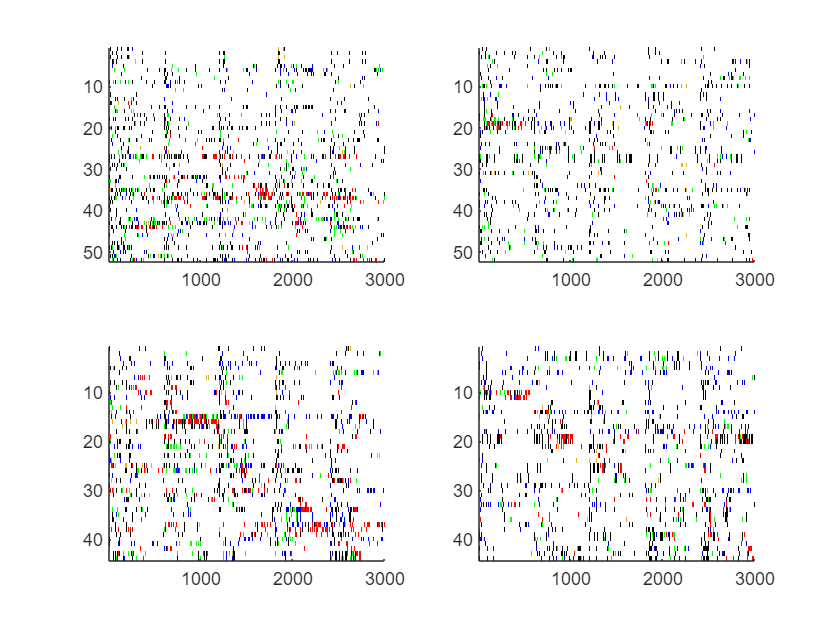


soFs = sortorders;
soMs = sortorderMs;

soFc = sortorderc;
soMc = sortorderMc;
    load colormap_white_discrete
%    load colormap_newcm
%for j = 1:2
 
new_cm = cnew;

figure
     subplot(2,2,1); 
    im_f = imagesc(cdsum_str(soFs, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off

    subplot(2,2,2); 
    im_f = imagesc(cdsum_cag(soFc, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off    
    
 subplot(2,2,3); 
    im_f = imagesc(cdsum_strM(soMs, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off

  subplot(2,2,4); 
    im_f = imagesc(cdsum_cagM(soMc, :));
    set(get(im_f, 'Parent'), 'Colormap', new_cm);
    box off

    %end
    

## II. Figure of averaged, cumulative sums across sessions


%     
% for sex = 1:2
%     if sex == 1
%         cumdegutableT = cumdegutable;
%     elseif sex == 2
%         cumdegutableT = cumdegutableM;
%     end
% figure
%     for type2use = 1:5
%         
% %                for k = 6:25
%                     subplot(5,1,type2use)
%                     imagesc(squeeze(nanmean(cumdegutableT(:,6:24,:,type2use)))');
%  %               end
% %            end
%         end
% end

## I. Analysis of distribution of behaviors (magnitude, location)

Here the goal is to quantify how uneven the behavioral distribution is. We're looking for the maximum, positive deviation from linear for each behavior, each session. The underlying assumptions are that 1) behavior is not evenly distributed across the session, and 2) there is a "flattening out" at some point in the session (i.e., the amount of behavior is not steadily increasing--there is at least some point of decrease). 

The question is whether 

1) this changes across days

2) this differs in S vs. C,

3) new cagemates differ from old stranger/cagemates


cs_posdev = cell(2,1);
cs_posdev_loc = cell(2,1); 



    
for sex = 1:2
    if sex == 1
        cumdegutableT = cumdegutable;
        cs_posdev{sex} = nan(size(cumdegutable,1), 25, 5);
        cs_posdev_loc{sex} = nan(size(cumdegutable, 1), 25, 5);
    elseif sex == 2
        cumdegutableT = cumdegutableM;
        cs_posdev{sex} = nan(size(cumdegutableM,1), 25, 5);
        cs_posdev_loc{sex} = nan(size(cumdegutableM, 1), 25, 5);
    end


    cursess = nan(4,5);
    for type2use = 1:5
        for i = 1:size(cumdegutableT,1)
                for k = 6:25
                    if ~isnan(cumdegutable(i,k,10,type2use)) 
                        curcumsum = squeeze(cumdegutableT(i,k, :, type2use));
                        [devfromlin, locdev] = cumsumDev(curcumsum);  
                        cs_posdev_loc{sex}(i,k, type2use) = locdev(1);
                        cs_posdev{sex}(i,k, type2use) = devfromlin(1);
                    end
                end
            end
        end
end


## IV. Figure and analysis of cumulative sums across sessions



indpartnersF = nan(size(degutable,1), 3);        
indpartnersM = nan(size(degutableM,1), 3);
for i = 1:size(degutable)
    indpartnersF(i,1) = find(degutable(:,1,1) == degutable(i,2,1));
    indpartnersF(i,2) = find(degutable(:,1,1) == degutable(i,3,1));
    indpartnersF(i,3) = find(degutable(:,1,1) == degutable(i,4,1));
end
    
for i = 1:size(degutableM)
    indpartnersM(i,1) = find(degutableM(:,1,1) == degutableM(i,2,1));
    indpartnersM(i,2) = find(degutableM(:,1,1) == degutableM(i,3,1));
    indpartnersM(i,3) = find(degutableM(:,1,1) == degutableM(i,4,1));
end



cs_posdevA = cell(2,1);
cs_posdevA_loc = cell(2,1); 
cs_min = cell(2,1)   

cs_min = 2×1 cell array
    {0×0 double}
    {0×0 double}



cumsumbehavIDFF = Rdb_CumSumFF(rdb_rr, betypes, 0);
cumdegutable = CumSumTableFF(dtt(:,1), rdb_rr, cumsumbehavIDFF);
cumdegutableM = CumSumTableFF(dttM(:,1), rdb_rr, cumsumbehavIDFF); %female degu table but with cumsums (note it's 4D)


for sex = 1:2
    if sex == 1
        cumdegutableT = cumdegutable;
        indpartners = indpartnersF;
        cs_posdevA{sex} = nan(size(cumdegutable,1), 2);
        cs_posdevA_loc{sex} = nan(size(cumdegutable, 1), 2);
        cs_min{sex} = nan(size(cumdegutable,1), 100, 2);
    elseif sex == 2
        cumdegutableT = cumdegutableM;
        indpartners = indpartnersM;
        cs_posdevA{sex} = nan(size(cumdegutableM,1), 2);
        cs_posdevA_loc{sex} = nan(size(cumdegutableM, 1), 2);
        cs_min{sex} = nan(size(cumdegutableM,1), 100, 2);
    end

    type2use = 1;

    cursessA(1,:) = 6:10;   % cagemate
    cursessA(2,:) = 11:15;  % stranger

    newcumsums = nan(size(cumdegutableT,1), size(cumdegutableT,3)*5, 2);

    for i = 1:size(cumdegutableT,1)
        for j = 1:2
            cursess = cursessA(j,:);
            curcumsums = squeeze(cumdegutableT(i,cursess, :, type2use));
            %this should be a 5 x 601 matrix, we need to convert to a 3005 x 1
            %vector        
            lastval = 0;
            for k = 1:5
                newcumsums(i, ((k-1)*601) + (1:601), j) = lastval + curcumsums(k,:);
                lastval = curcumsums(k,end) + lastval;
            end
            [devfromlin, locdev] = cumsumDev(squeeze(newcumsums(i, :, j))); 
            cs_posdevA_loc{sex}(i,j) = locdev(1);
            cs_posdevA{sex}(i,j) = devfromlin(1);
            cs_min{sex}(i,:,j) = newcumsums(i,1:30:3000,j);
        end

    end
end

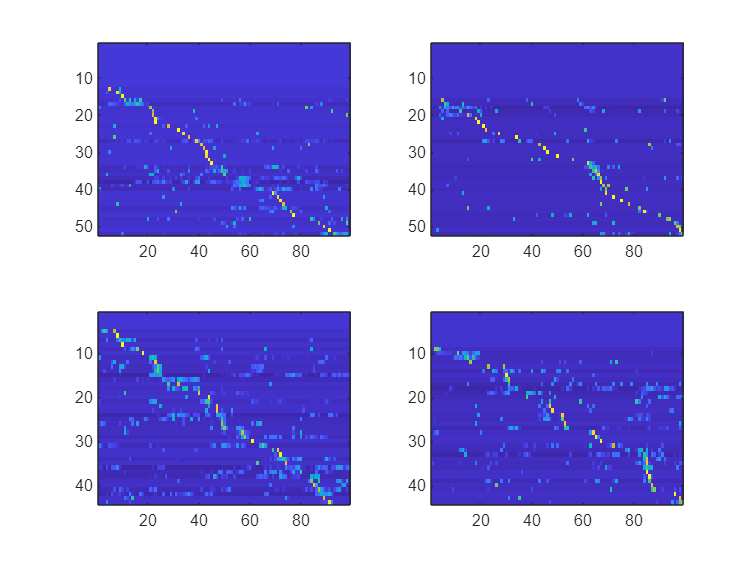

%watch the indices. Keeping stranger as "2" in the main indices, but
%plotting it in first plot

figure 
subplot(2,2,1)
zdc = zscore(diff(cs_min{1}(:,:,2)'))';
[~, maxlocz{1,2}] = max(zdc');
[b, imlz{1,2}] = sort(maxlocz{1,2});
imagesc(zdc(imlz{1,2},:));

subplot(2,2,2)
zdc = zscore(diff(cs_min{1}(:,:,1)'))';
[~, maxlocz{1,1}] = max(zdc');
[b, imlz{1,1}] = sort(maxlocz{1,1});
imagesc(zdc(imlz{1,1},:));

subplot(2,2,3)
zdc = zscore(diff(cs_min{2}(:,:,2)'))';
[~, maxlocz{2,2}] = max(zdc');
[b, imlz{2,2}] = sort(maxlocz{2,2});
imagesc(zdc(imlz{2,2},:));

subplot(2,2,4)
zdc = zscore(diff(cs_min{2}(:,:,1)'))';
[~, maxlocz{2,1}] = max(zdc');
[b, imlz{2,1}] = sort(maxlocz{2,1});
imagesc(zdc(imlz{2,1},:));

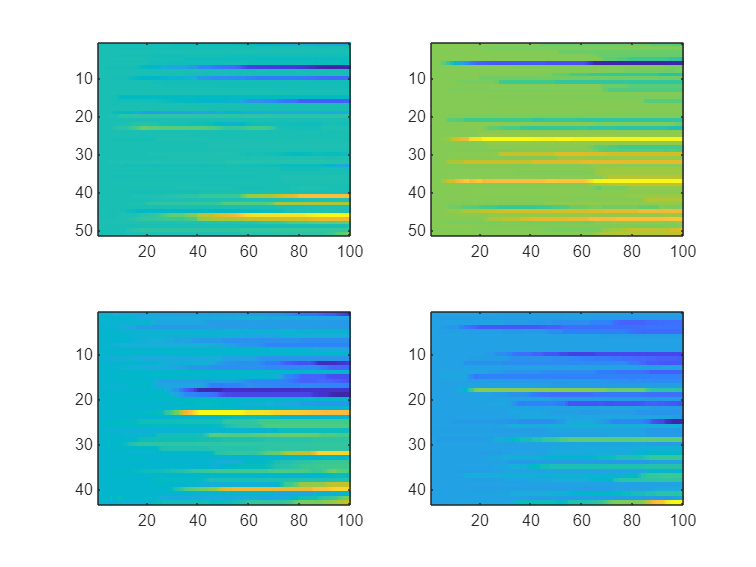

clear iml
%stranger female
figure 
subplot(2,2,1)
dc = diff(cs_min{1}(:,:,2));
[~, maxloc] = max(dc');
[b, iml{1,1}] = sort(maxloc);
imagesc(dc(iml{1,1},:));

%cagemate female
subplot(2,2,2)
dc = diff(cs_min{1}(:,:,1));
[~, maxloc] = max(dc');
[b, iml{1,2}] = sort(maxloc);
imagesc(dc(iml{1,2},:));

%stranger male
subplot(2,2,3)
dc = diff(cs_min{2}(:,:,2));
[~, maxloc] = max(dc');
[b, iml{2,1}] = sort(maxloc);
imagesc(dc(iml{2,1},:));

%cagemate male
subplot(2,2,4)
dc = diff(cs_min{2}(:,:,1));
[~, maxloc] = max(dc');
[b, iml{2,2}] = sort(maxloc);
imagesc(dc(iml{2,2},:));

%Now need to look at asymmetry before vs. after the high agonistic bin
% prediction is that asymmetry increases
% testing by subtracting partner agonistic cumsum from main degu agonistic
% cumsum, divided by sum of both
%

% unfortunately, we now have to go from individual back to dyad. This is
% going to be a huge pain. We'll do this by removing the partner from the
% full list ("fullset_fs" and "fullset_fc") on each iteration

agasym = cell(2,1);
alluniqueinds = cell(2,1);
prepost = cell(2,2);
for sex = 1:2
        if sex == 1
            indpartners = indpartnersF;
        else

            indpartners = indpartnersM;
        end
        alluniqueinds{sex} = nan(size(indpartners, 1)/2, 1);        
    for strorcag = 1:2 %1 = cagemate, 2 = str
        fullset = 1:size(cs_min{sex},1);
        agasym{sex}(:,:,strorcag) = nan(size(indpartners,1)/2, size(cs_min{sex},2));
        i = 1;
        while ~isempty(fullset)
            curagstr = cs_min{sex}(fullset(1),:,strorcag);
            indpartner = indpartners(fullset(1), strorcag); 
            curagstr_part = cs_min{sex}(indpartner, :, strorcag);

            agasym{sex}(i,:,strorcag) = abs(curagstr-curagstr_part)./(curagstr+curagstr_part);
            combined = diff(cs_min{sex}(fullset(1),:,strorcag) + cs_min{sex}(indpartner, :, strorcag));
            [maxcomb(i) maxlocomb(i)] = max(combined);
            
            if maxlocomb(i) > 1
                pre_cur = curagstr(maxlocomb(i)-1);
                pre_part = curagstr_part(maxlocomb(i)-1);
                post_cur = curagstr(end)-curagstr(maxlocomb(i)+1);
                post_part = curagstr_part(end)-curagstr_part(maxlocomb(i)+1);
            else
                pre_cur = nan;
                pre_part = nan;
                post_cur = nan;
                post_part = nan;
            end

            prepost{sex,strorcag}(i,1) = abs(pre_cur-pre_part)/(pre_cur+pre_part);
            prepost{sex,strorcag}(i,2) = abs(post_cur - post_part)/(post_cur + post_part);


            alluniqueinds{sex}(i,strorcag) = fullset(1);
            fullset = fullset(2:end);
            fullset = setdiff(fullset, indpartner); 
            i = i+1;
        end
    end
end




figure
subplot(1,2,1)
hold

Current plot held


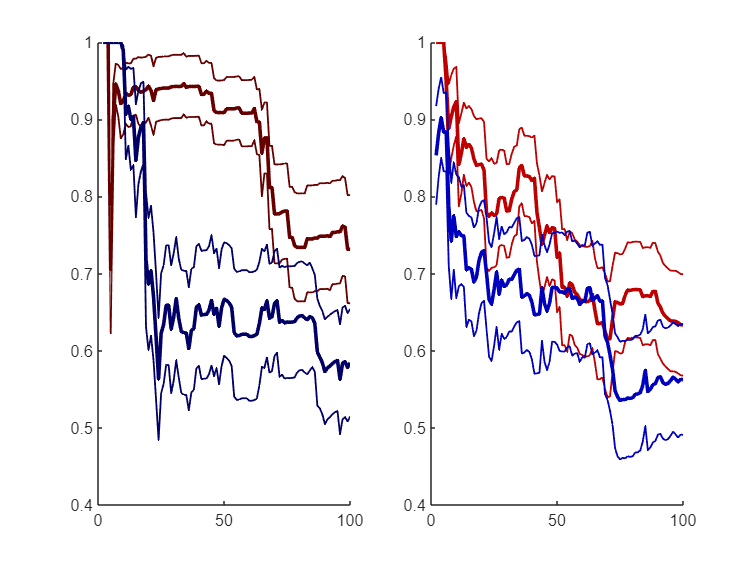

errorbar_alt(1:100, nanmean(agasym{1}(:,:,1)), nanstd(agasym{1}(:,:,1))/sqrt(size(agasym{1},1)-1), 'Color', colorcodes_f(2,:));
errorbar_alt(1:100, nanmean(agasym{2}(:,:,1)), nanstd(agasym{2}(:,:,1))/sqrt(size(agasym{2},1)-1), 'Color', colorcodes_m(2,:));
box off
subplot(1,2,2)
errorbar_alt(1:100, nanmean(agasym{1}(:,:,2)), nanstd(agasym{1}(:,:,2))/sqrt(size(agasym{1},1)-1), 'Color', colorcodes_f(1,:));
errorbar_alt(1:100, nanmean(agasym{2}(:,:,2)), nanstd(agasym{2}(:,:,2))/sqrt(size(agasym{2},1)-1), 'Color', colorcodes_m(1,:));
box off


% prepost = cell(2,2);
% 
% for sex = 1:2
%     for strorcag = 1:2  
%         prepost{sex,strorcag} = nan(size(agasym{sex},1), 2);
%         for i = 1:size(alluniqueinds{sex},1)
%             curmaxloc = maxlocz{sex,strorcag}(alluniqueinds{sex}(i,strorcag));
%             if curmaxloc > 1
%                 agasym{sex}(i,:,strorcag) = abs(curagstr-curagstr_part)./(curagstr+curagstr_part);
%                 preagasym = nanmean(agasym{sex}(i,1:curmaxloc,strorcag));
%                 postagasym = nanmean(agasym{sex}(i,curmaxloc+1:end,strorcag));
%                 prepost{sex,strorcag}(i,1:2) = [preagasym postagasym];
%             end
% %              if prepost{sex,strorcag}(i,2) < .11
% 
% %                  dbs = 1;
% %              end
%         end
%     end
% end



Plot distributions

alldists = reshape(cs_min{2}, 1, []);
[~, allhist_b] = hist(alldists, 30);
ag_hist = cell(2,1);
skew_met = nan(size(cs_min{1},1), 2, 2);

for i = 1:length(cs_min)
    ag_hist{i} = nan(size(cs_min{i},1), 30, 2);
    for j = 1:size(cs_min{i},1)
        for k = 1:2
            [a b] = hist(cs_min{i}(j,:,k), allhist_b);
            ag_hist{i}(j,:,k) = a;
            skew_met(j,k,i) = skewness(cs_min{i}(j,:,k));
        end
    end
end

f = figure;
subplot(2,1,2)
e1 = errorbar(nanmean(prepost{1,2}), nanstd(prepost{1,2}/sqrt(length(find(~isnan(prepost{1,2}(:,1)))))), 'Color', colorcodes_f(1,:));
hold

Current plot held


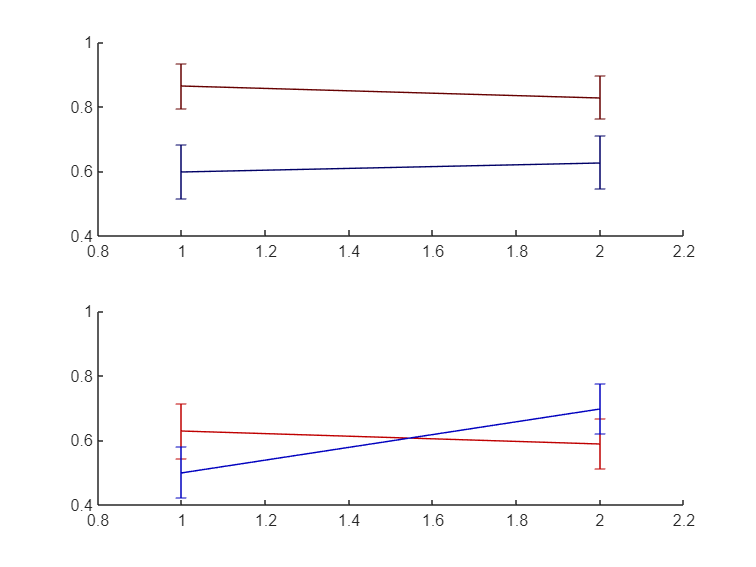

errorbar(nanmean(prepost{2,2}), nanstd(prepost{2,2}/sqrt(length(find(~isnan(prepost{2,2}(:,1)))))), 'Color', colorcodes_m(1,:))
box off
set(get(e1, 'Parent'), 'XLim', [.8 2.2]);
set(get(e1, 'Parent'), 'YLim', [.4 1]);
subplot(2,1,1)
e1 = errorbar(nanmean(prepost{1,1}), nanstd(prepost{1,1}/sqrt(length(find(~isnan(prepost{1,1}(:,1)))))), 'Color', colorcodes_f(2,:));
hold on
errorbar(nanmean(prepost{2,1}), nanstd(prepost{2,1}/sqrt(length(find(~isnan(prepost{2,1}(:,1)))))), 'Color', colorcodes_m(2,:))
box off
set(get(e1, 'Parent'), 'XLim', [.8 2.2]);
set(get(e1, 'Parent'), 'YLim', [.4 1]);



%[tbl,rm] = simple_mixed_anova(allbyday_m, [], {'exposureday' 'cagstr'})
anovamat = cat(3,[prepost{1,1} ; prepost{2,1}] , [prepost{1,2} ; prepost{2,2}]);
[tbl,rm] = simple_mixed_anova(anovamat, [ones(size(prepost{1,1},1),1) ; 2*ones(size(prepost{2,1},1),1)], {'preVpost' 'cagVstr'}, {'femaleVmale'})

tbl = 12×8 table
                                      SumSq      DF     MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                                    _________    __    _________    ________    __________    __________    __________    __________

    (Intercept)                        22.589     1       22.589      195.73    5.1708e-10    5.1708e-10    5.1708e-10    5.1708e-10
    femaleVmale                       0.33701     1      0.33701      2.9201       0.10809       0.10809       0.10809       0.10809
    Error                              1.7312    15      0.11541                                                               

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [48×5 table]
         ResponseNames: {'Y001'  'Y002'  'Y003'  'Y004'}
    BetweenFactorNames: {'femaleVmale'}
          BetweenModel: '1 + femaleVmale'

   Within Subjects:
          WithinDesign: [4×2 table]
     WithinFactorNames: {'preVpost'  'cagVstr'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×4 table]
            Covariance: [4×4 table]


anovamat2 = [prepost{1,2} ; prepost{2,2}];
[tbl,rm] = simple_mixed_anova(anovamat2, [ones(size(prepost{1,1},1),1) ; 2*ones(size(prepost{2,1},1),1)], {'preVpost'}, {'femaleVmale'})

tbl = 6×8 table
                              SumSq       DF      MeanSq          F           pValue       pValueGG      pValueHF      pValueLB 
                            __________    __    __________    __________    __________    __________    __________    __________

    (Intercept)                 23.658     1        23.658        162.05    7.5256e-14    7.5256e-14    7.5256e-14    7.5256e-14
    femaleVmale             5.5612e-07     1    5.5612e-07    3.8092e-06       0.99846       0.99846       0.99846       0.99846
    Error                       4.5258    31       0.14599                                                                      
    (In

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [48×3 table]
         ResponseNames: {'Y001'  'Y002'}
    BetweenFactorNames: {'femaleVmale'}
          BetweenModel: '1 + femaleVmale'

   Within Subjects:
          WithinDesign: [2×1 table]
     WithinFactorNames: {'preVpost'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×2 table]
            Covariance: [2×2 table]


anovamat2 = [prepost{1,1} ; prepost{2,1}];
[tbl,rm] = simple_mixed_anova(anovamat2, [ones(size(prepost{1,1},1),1) ; 2*ones(size(prepost{2,1},1),1)], {'preVpost'}, {'femaleVmale'})

tbl = 6×8 table
                              SumSq      DF     MeanSq         F          pValue       pValueGG      pValueHF      pValueLB 
                            _________    __    _________    ________    __________    __________    __________    __________

    (Intercept)                28.203     1       28.203       205.1    1.4855e-13    1.4855e-13    1.4855e-13    1.4855e-13
    femaleVmale               0.64891     1      0.64891      4.7191      0.039516      0.039516      0.039516      0.039516
    Error                      3.4377    25      0.13751                                                                    
    (Intercept):preVpost

rm =   RepeatedMeasuresModel with properties:

   Between Subjects:
         BetweenDesign: [48×3 table]
         ResponseNames: {'Y001'  'Y002'}
    BetweenFactorNames: {'femaleVmale'}
          BetweenModel: '1 + femaleVmale'

   Within Subjects:
          WithinDesign: [2×1 table]
     WithinFactorNames: {'preVpost'}
           WithinModel: 'separatemeans'

   Estimates:
          Coefficients: [2×2 table]
            Covariance: [2×2 table]



colorFM = [1 0 0  ; 0 0 1];

figure
hold

Current plot held


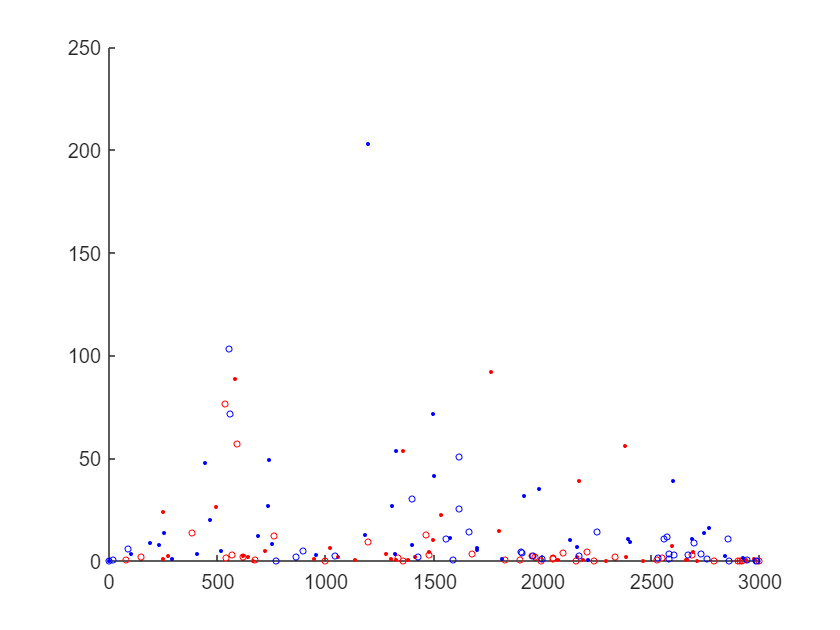

for i = 1:2
    plot(cs_posdevA_loc{i}(:,1), cs_posdevA{i}(:,1), 'o', 'Color', colorFM(i,:), 'MarkerSize', 3);
    plot(cs_posdevA_loc{i}(:,2), cs_posdevA{i}(:,2), '.', 'Color', colorFM(i,:), 'MarkerSize', 6);
end

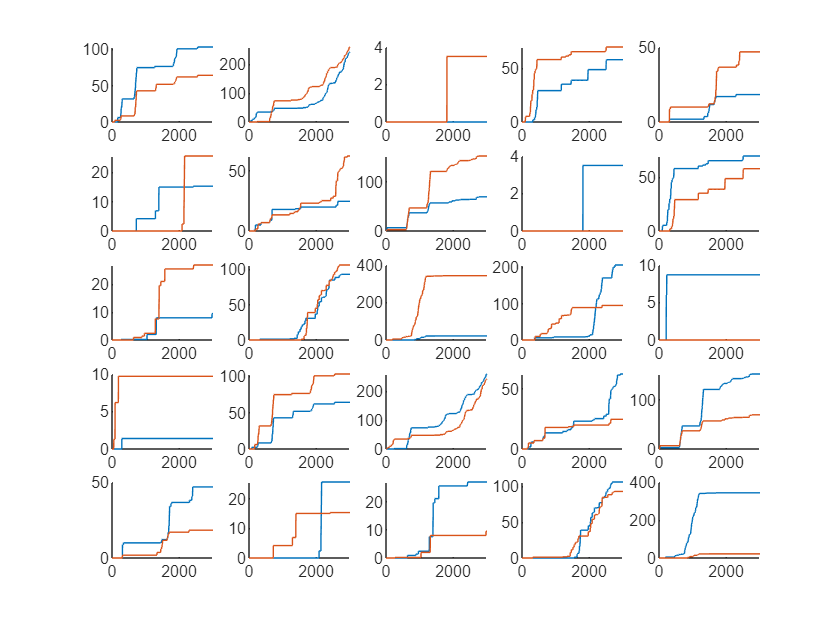

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held



%test -- look at figures
figure
for i = 1:25
    subplot(5,5,i)
    plot(newcumsums(i,:,2))
    hold    
    plot(newcumsums(indpartners(i,2),:,2))
%    plot(newcumsums(indpartnersM()))
    box off
end


x = 1:3005;


for i = 1:size(newcumsums,1)
    for j = 1:2
        [ Qpre(i,:,j), pmodel(i,:,j), smodel(i,:,j)] = fit_logistic(1:3005,newcumsums(i,:,j));
        
    end
end

max number of iterations reached...exiting
normalized epsilon: 1.7511


max number of iterations reached...exiting
normalized epsilon: 678.0065


max number of iterations reached...exiting
normalized epsilon: 689.17


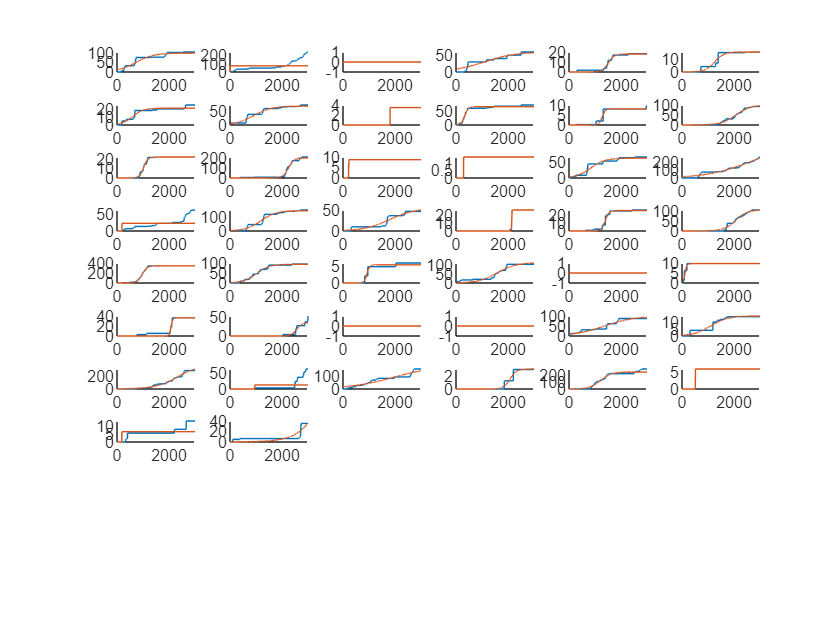

Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held
Current plot held



figure
for i = 1:size(newcumsums,1)
    subplot(10,6,i)
    plot(newcumsums(i,:,2))

    hold    
    plot(Qpre(i,:,2));
%    plot(newcumsums(indpartnersM()))
    box off
end

% 
% end

